================================================================================

# Práctica 12. EDOs

#### Problema 1. Métodos de Euler en el sistema masa-resorte-amortiguador (MRA)

Consideramos el clásico sistema físico con una masa $m$ conectada a un muelle o resorte con constante elástica $k$ y un amortiguador con coeficiente de amortiguamiento $c$: 

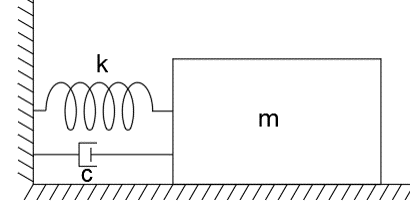

La ecuación del movimiento de la masa (sin rozamiento) viene dada por ${\displaystyle m{\ddot {x}} = -kx-c{\dot {x}}}$.

Es común escribir esta ecuación usando otras parámetros que ayudan mejor a entender el comportamiento del sistema, concretamente la frecuencia natural $\omega_N = \sqrt{\frac{k}{m}}$ y el factor de amortiguación $\zeta = \frac{c}{2\sqrt{km}}$. Con ellos, la ecuación del movimiento es:

$\ddot x + 2\zeta \omega_N \dot x + \omega_N ^2 x = 0$.

Para este ejercicio asumimos $\omega_N =3\pi$ y $\zeta=0.3$.

- Transformar a mano la ecuación del movimiento en un sistema de EDOs de primer orden. Escribir una función simbólica para la ecuación del movimiento de orden dos y usar la función $\texttt{odeToVectorField()}$ para comprobar los resultados. Observar que el sistema de EDOs es lineal y autónomo. Escribir la matriz del sistema $A$.

clear all

wn = 3*pi

wn =    9.424777960769379


amort = 0.3

amort =    0.300000000000000


%  Si la ecuacion del movimiento es:  xpp + 2*amort*wn*xp + wn^2 * x = 0
%  Significa que:

%  xpp = 0
%  2*amort*wn*xp = 0
%  wn^2 * x = 0

%  Aislando xpp:
%  xpp = -2*amort*wn*xp - wn^2*x

syms Y1
syms Y2

dy1 = Y2

$$dy1 = Y_{2}$$

dy2 = -2*amort*wn*Y2 - wn^2*Y1

$$dy2 = -\frac{3125302502557517\,Y_{1}}{35184372088832}-\frac{9\,\pi \,Y_{2}}{5}$$

sistema = [dy1 ; dy2]

$$sistema = \left(\begin{array}{c} Y_{2}\\ -\frac{3125302502557517\,Y_{1}}{35184372088832}-\frac{9\,\pi \,Y_{2}}{5} \end{array}\right)$$

A = [0 1 ; -wn^2 -2*amort*wn]

A =                    0   1.000000000000000
 -88.826439609804225  -5.654866776461628


syms x(t)

movimiento = diff(x,2) + 2*amort*wn*diff(x) + wn^2 * x == 0;

result_matlab = odeToVectorField(movimiento)

$$result\_matlab = \left(\begin{array}{c} Y_{2}\\ -\frac{9\,\pi \,Y_{2}}{5}-\frac{3125302502557517\,Y_{1}}{35184372088832} \end{array}\right)$$

- Dibujar el campo vectorial resultante con la función $\texttt{quiver()}$ de MATLAB. Para ello grear una malla $\texttt{meshgrid(-2:0.1:2, -20:1.2:15)}$.

[X, Y] = meshgrid(-2:0.1:2, -20:1.2:15);
U = Y;   % Evaluar X=Y1, Y=Y2 en sistema(1)
V = -2*amort*wn*Y - wn^2*X;
quiver(X, Y, U, V)
hold on

Consideramos el PVI con condiciones iniciales $x(0) = 2$ y $\dot x (0) = 0$. Buscamos la trayectora en el intervalo de tiempo $[0, 8]$.

- Integrar (encontrar la trayectoria) usando la fórmula de Euler explícita con $h=0.05$ (crear esta variable `h` y trabajar con ella de manera que se pueda modificar). Dibujar la posición $x$ frente a la velocidad $\dot x$ de la solución sobre el campo vectorial.

h = 0.05;
t = 0:h:8;

pose0 = [2 0]

pose0 =      2     0


poses(1,:) = pose0;
index = 1;
for i = 1:length(t)
    index = index + 1;
    poses(index,:) = poses(index-1,:)' + h * A * poses(index-1,:)';
end

poses

poses =    2.000000000000000                   0
   2.000000000000000  -8.882643960980422
   1.555867801950979 -15.253779510856559
   0.793178826408151 -17.850984829827738
  -0.099370415083236 -16.326500333948019
  -0.915695431780637 -11.268955109511790
  -1.479143187256227  -4.015834868199185
  -1.679934930666186   3.688966840451029
  -1.495486588643634  10.107067972535301
  -0.990133190016869  13.891299285940134


- Hacer una representación gráfica de $x$ en el tiempo en rojo.

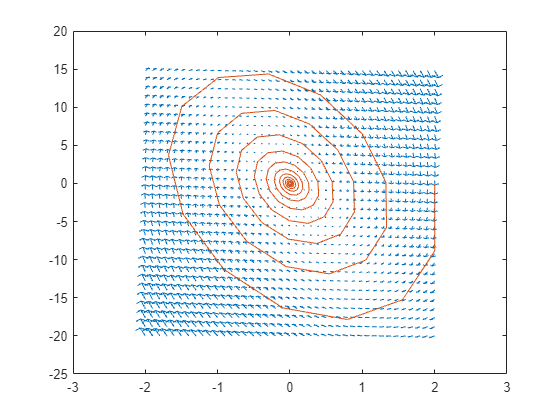

plot(poses(:,1),poses(:,2))

- Encontrar la solución ahora usando la fórmula de Euler implícita (con la misma $h$). Añadir a la gráfica anterior esta solución en verde.

- Encontrar la (mejor) solución que da Matlab con la función $\texttt{ode45()}$ y añadira a la gráfica en negro.

- Observar qué sucede cuando cambiamos $h=0.001$ y $h = 0.1$. ¿Qué está pasando?

#### Problema 2. Método de Runge-Kutta RK4

Implementar el método RK4 para una EDO $\dot y = f(t,y)$. La función debe tomar como argumentos:

- la función $f$, 

- el valor inicial $y(t_0)$,

- el paso $h$ para el método,

- el intervalo de integración $[t_0,t_{max}]$

Y debe devolver la solución discretizada (trayectoria) y, si se quiere, la discretización de $t$ usada.

Consideramos los siguientes PVIs:

- $y' = -y + t + 1, \quad 0 \leq t \leq 1, \quad y(0) = 1$,

- $y' = te^{3t} - 2y, \quad 0 \leq t \leq 1, \quad y(0) = 0$,

- $y' = \cos(2t) + sin(3t), \quad 0\leq t\leq 1, \quad y(0) = 1$.

Para cada uno de ellos calculamos la solución con $t\in[0,1]$ usando tres métodos:

-  La implementación realizada de $\texttt{RK4}$.

-  La función$\texttt{ode45}$de MATLAB.

-  La solución analítica con la función `dsolve` de MATLAB o con las soluciones analíticas siguienetes, respectivamente:

$y(t) = e^{-t} + t$,

$y(t) = \frac15 t e^{3t} - \frac{1}{25}e^{3t} + \frac{1}{25}e^{-2t}$,

$y(t) = \frac12 \sin(2t) - \frac13 \cos(3t) + \frac43$.

Representar gráficamente la solución analítica (continua) y las soluciones con $\texttt{RK4}$ y $\texttt{ode45}$ con asteriscos de distintos colores. 

Para comparar más a fondo los métodos, calcular el error absoluto entre las soluciones obtenidas por $\texttt{RK4}$ y $\texttt{ode45}$ y la solución analítica. Hacer un gráfico que muestre los errores de cada una de las tres fórmulas.

clear all
format long


#### Funciones internas

`Documento preparado por I. Parada, 22 de mayo de 2024`